## This script solves for the steady-state temperature in the nano-capillary by performing FEA on a 2D, axisymmetric mesh.

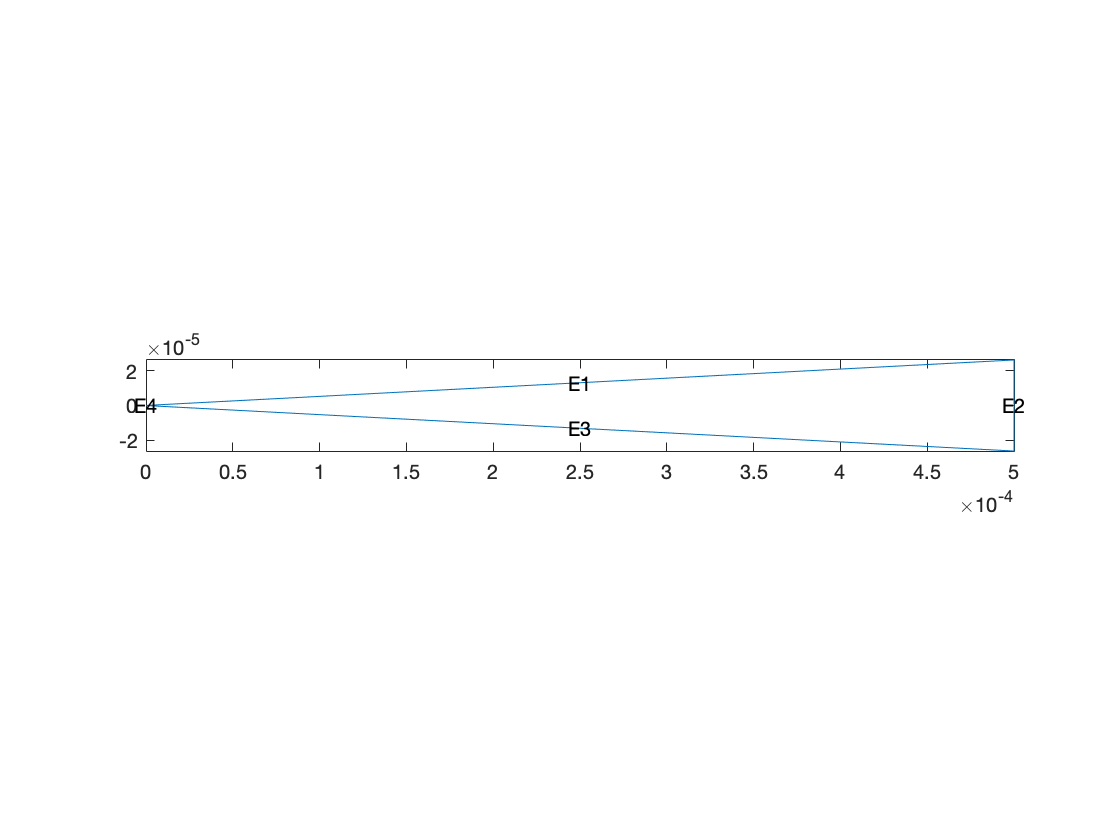

%GEOMETRY

%creates model bin and defines model type as axisymmetric
tmodel = createpde("thermal", "steadystate-axisymmetric");

%MANUALLY DEFINE GEOMETRY

r_0 = 20*10^(-9);
length = 500*10^(-6);

base_radius = r_0 + (length)*tan(3*pi/180);

%manually define geometry
g = decsg([2 4 0 length length 0 r_0 base_radius -base_radius -r_0]');

geometryFromEdges(tmodel, g);

figure
pdegplot(tmodel,'EdgeLabels','on');
axis equal;

%DEFINE BOUNDARY CONDITIONS

u = symunit;

%zero heat flux through wall of cone
thermalBC(tmodel, "Edge", 1, "HeatFlux", 0);
 
%zero heat flux through wall of cone
thermalBC(tmodel, "Edge", 3, "HeatFlux", 0);
 
%constant temperature of 25degC at base of cone
thermalBC(tmodel, "Edge", 2, "Temperature", 25);
 
%zero heat flux through tip
thermalBC(tmodel, "Edge", 4, "HeatFlux", 0);
 

%DEFINE PHYSICAL CONSTANTS
    
k = vpa(.6) *u.Watt/(u.m*u.Celsius);

%remove units so that it may be input into a function
k = double(separateUnits(k));

rho_m = 997; %mass density of water in kg/m^3
c_spec = 4.184*(10^3.0); %specific heat capacity of water in J/(kg*C)
 
%define thermal properties in cone
thermalProperties(tmodel, "ThermalConductivity", k);


%DEFINE INTERNAL POWER GENERATION
 
%parameters for defining internal power generation 
% (generated by python script)

a = ;
b = ;
c = ;
 
% %define function for internal power generation
q = @(location,state)(10^10)*(a*exp(-b*10^6*location.x)+c);

  
internalHeatSource(tmodel, q);

                    

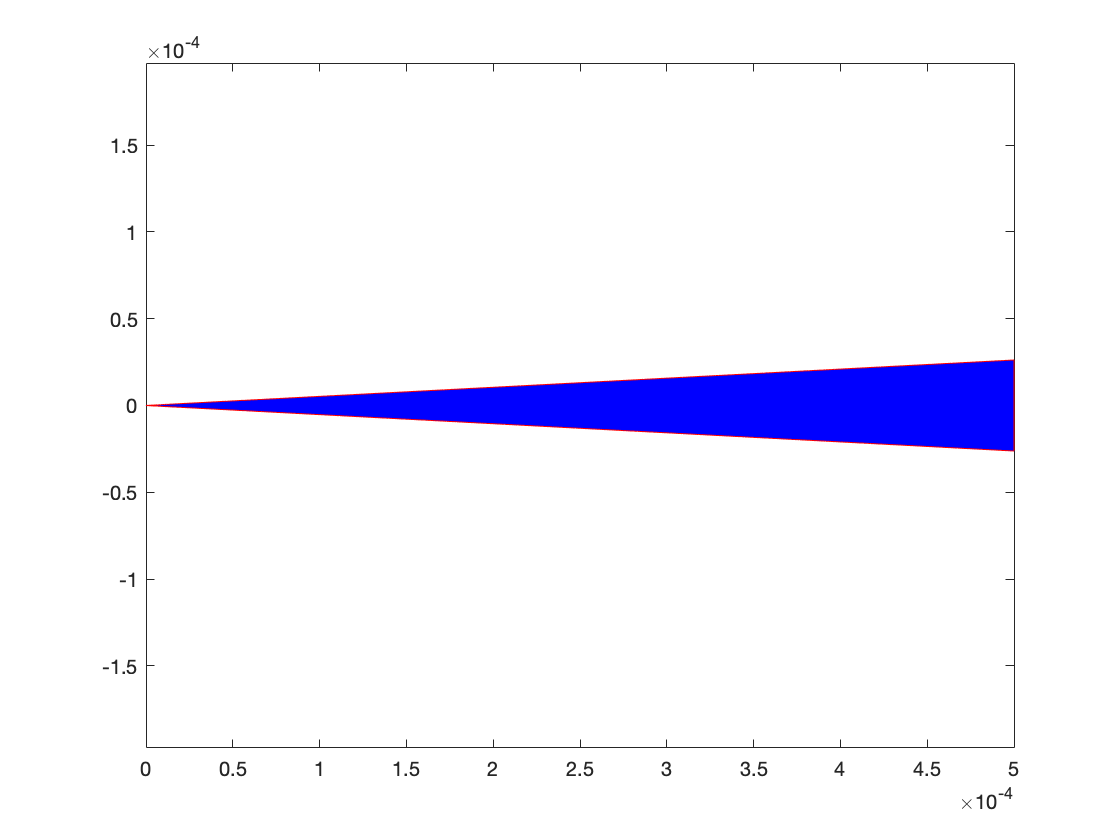

%CREATE MESH AND SOLVE MODEL

%create and display mesh
msh = generateMesh(tmodel, "Hmax", .00000015, "Hmin", .0000001);
 
figure;
pdemesh(tmodel, "FaceAlpha", 0.5); 

 
 
 
%SOLVE AND PLOT MODEL
      
tic
results = solve(tmodel);
time = toc

time = 111.6393


t_max = max(results.Temperature);
t_min = min(results.Temperature);
disp(t_max);

   25.6956



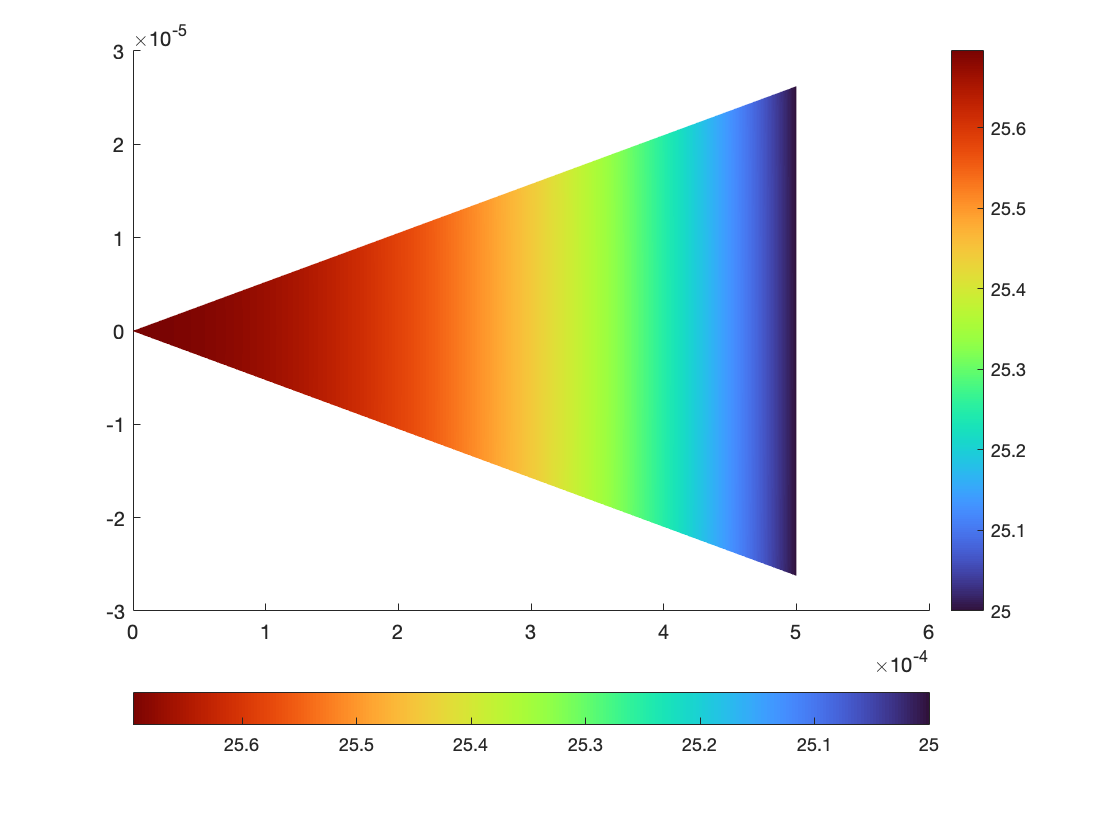



pdeplot(tmodel,'XYData', results.Temperature, 'ColorMap','turbo');
c = colorbar('southoutside', "direction", "reverse");

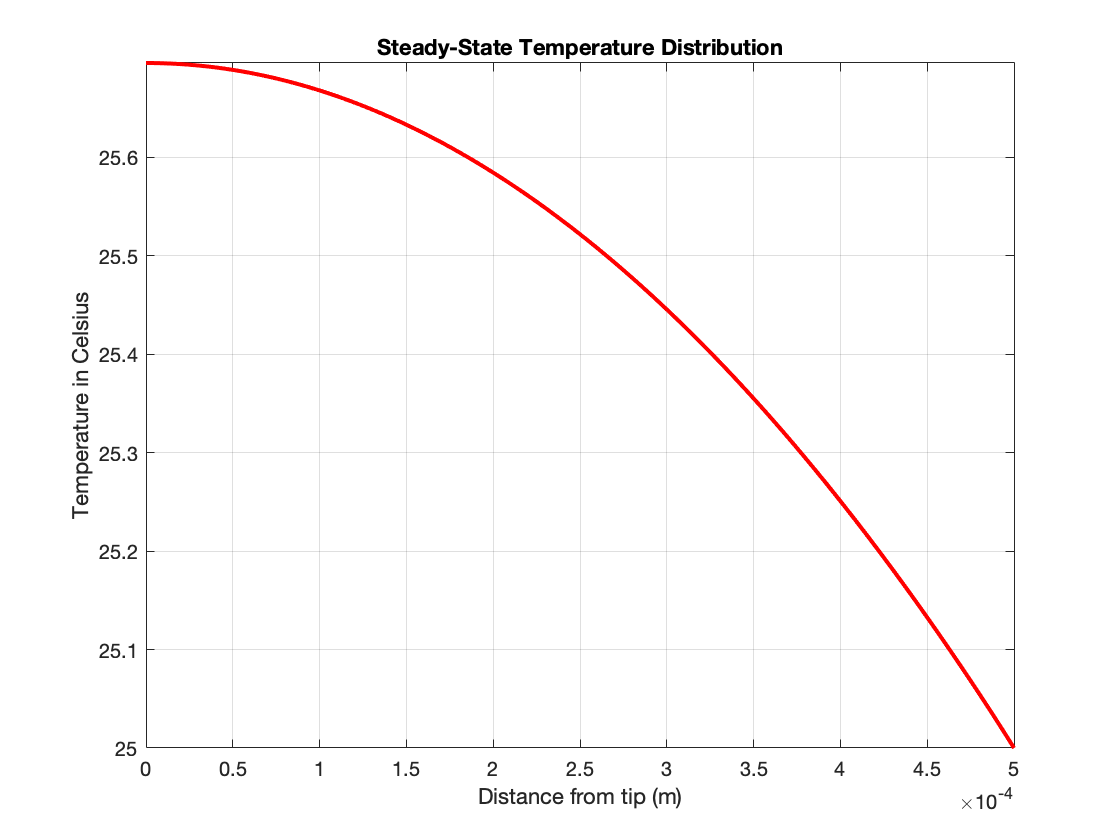

%POST PROCESSING RESULTS
%PLOTTING TEMPERATURE DISTRIBUTION

%Create vector for all of the nodes on axis of symmetry
X = 0.0:0.01*10^(-4):5*10^(-4);
Y = zeros(size(X));

%Interpolate temperature at nodes along x axis
Tintrp = interpolateTemperature(results,X,Y);

Y_UV = 25*ones(size(X));

%reshape interpolated 
Tintrp = reshape(Tintrp,size(X));

%Save x and y data as .mat file to import into python
save("/Users/Jacob/Desktop/Python/temp_distribution_222.mat", "X", "Tintrp");

%create plot of temperature distribution
figure
plot(X, Tintrp, "LineWidth", 2, "Color", "red");
hold on
title("Steady-State Temperature Distribution");
xlabel("Distance from tip (m)");
ylabel("Temperature in Celsius");
grid on

xlim([0, 5*10^(-4)]);
ylim([t_min, t_max]);


disp(t_max)

   25.6956

